This script is a part of the supplementary material for the following paper:

-  Jamshidi Idaji et al,  "Nonlinear Interaction Decomposition (NID): A Method for Separation of Cross-frequency Coupled Sources in Human Brain". doi: [https://doi.org/10.1101/680397](https://doi.org/10.1101/680397)

(C) Please cite the above paper (or a future peer reviewd version) in case of any significant usage of this script.

Corresponding Author: Vadim V. Nikulin (nikulin@cbs.mpg.de)

(C) Mina Jamshidi Idaji, Oct 2019, @ MPI CBS, Leipzig, Germany

jamshidi@cbs.mpg.de    .         minajamshidi91@gmail.com

https://github.com/minajamshidi/NID

# **Supplementary Code (1)**

# **Filtering a Gaussian-distributed signal: the distribution of the filtered signal**

In this script, we will filter a white Gaussian noise with different bandwidths and investigate the impact of bandwidth of the filter on the distribution of the filtered signal.

We want to filter a 10-min white Gaussian noise:

fs = 256;
n_samples = 10*60*fs;
times = (0:n_samples-1)/fs;
sig = randn(1, n_samples);

Let's start with a bandwidth of 4Hz around central frequency of 10Hz:

filt_order = 10*fs + 1;
Wn1 = [8, 12];
[b1, b1_spec] = build_fir1(filt_order, Wn1, fs);
[y1, y1_spec] = filter_signal(b1, sig, fs);

Now, we can look at the distribution of the filtered signal and its time segments:

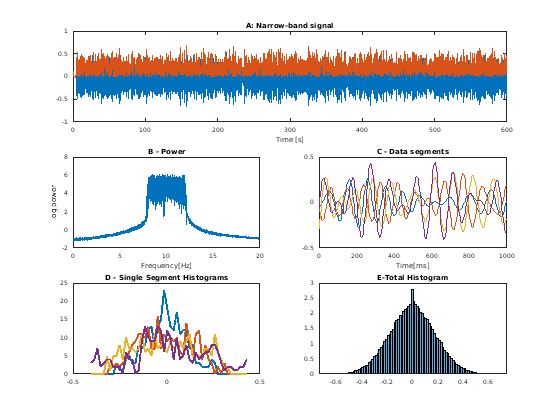

plot_fig(times, y1, y1_spec, fs)

- As it can be seen, the distribution of the whole time-series (panel E) can be approximated well with Gaussian distribution. Even the very-short data segments in panel C have bell-shaped histograms. This is actually because of the bandwidth of the narrow-band signal (panel B), which lets faster fluctuations appear in the amplitude-envelope.

Now, we set the bandwidth of the filter *very* narrow (0.2Hz) and plot the figure again:

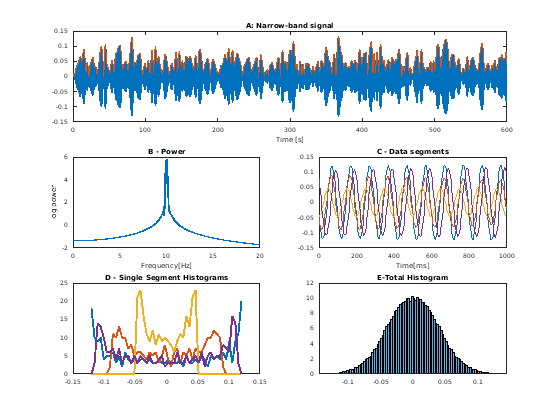

filt_order = 10*fs + 1;
Wn2 = [9.9, 10.1];
[b2, b2_spec] = build_fir1(filt_order, Wn2, fs);
[y2, y2_spec] = filter_signal(b2, sig, fs);
plot_fig(times, y2, y2_spec, fs)

- The first important observation is that because of very narrow bandwidth of the signal (panel B) the fluctuations of the  amplitude envelope are much slower than the previous case. This results in the observation that short data segments look like pure sinusoids with no fluctuation in their amplitude-envelope and their histograms (panel D) look *very* non-Gaussian, with peaks at the extremes. However, the whole-signal has a Gaussian distribution (pannel E).

## Conclusion

- The two simulations above illustrate the fact that  filtering of a Gaussian signal, as a linear transformation, results in a Gaussian signal. However, based on the width of the filter, more or less data points are required so that the histograms of the data segments are eligible to be assumed as approximations of data distribution.

## **Functions**

function plot_fig(times, y, y_spec, fs)
    FS = 5;
    LW = 1.5;
    figure;
    subplot(311) %A
    plot(times,y)
    hold on,
    plot(times, abs(hilbert(y)), 'linewidth',LW)
    xlabel('Time [s]')
    title('A: Narrow-band signal')
    set(gca,'fontsize',FS)
    
    subplot(323); %B
    plot(y_spec.f,log10(y_spec.pow),'linewidth', LW);
    xlim([0,20]);
    xlabel('Frequency[Hz]','fontsize',FS);
    ylabel('log power')
    title('B - Power','fontsize',FS);
    set(gca,'fontsize',FS)
    
    n_seg = 4;
    seg_len = 1*fs;
    y_segments = zeros(seg_len, n_seg);
    % select random segments
    m1 = randi(length(y) - seg_len, n_seg);
    for k = 1:n_seg
        y_segments(:, k) = y(m1(k):m1(k)+seg_len-1)';
    end
    
    subplot(324); %C
    xt = (0:seg_len-1)/fs*1000;
    plot(xt, y_segments,'linewidth', LW);
    xlabel('Time[ms]','fontsize', FS);
    title('C - Data segments','fontsize',FS);
    set(gca,'fontsize',FS)
    
    
    subplot(325); %D
    [r,c] = hist(y_segments, 50);
    plot(c,r, 'linewidth', LW)   
    title('D - Single Segment Histograms','fontsize',FS);
    set(gca,'fontsize',FS)
   
    subplot(326) %E
    hist(y, 100,'Normalization','pdf');
    title('E-Total Histogram','fontsize',FS);
    set(gca,'fontsize',FS)
    [r,c] = hist(y, 100);
    [fitresult, gof] = createFit(c, r);
    gof
    hold on,
    gauss = fitresult.a1*exp(-((c-fitresult.b1)/fitresult.c1).^2);
    plot(c, gauss, 'r', 'linewidth', 4)
end

A function for building the filter and returning its spectrum:

function  [b, spec] = build_fir1(order, Wn, fs)
    % INPUTS:
    % order: filter order
    % Wn [2x1]: pass-band frequencies
    % fs: sampling frequency
    % OUTPUTS:
    % b: filter coefficients
    % spec: spectrum of the filter
    Wn = Wn/(fs/2); % normalize the frequencies
    b = fir1(order, Wn);
    nfft = 2^ceil(2*log2(order));
    b_fft = fft(b ,nfft);
    f = (0:nfft-1)/nfft*fs;
    b_fft = b_fft(f<=20);
    f = f(f<=20);
    b_pow = abs(b_fft).^2;
    spec.f = f;
    spec.pow = b_pow;
end

A function for filtering a given signal:

function [y, spec] = filter_signal(b, sig, fs)
    % INPUTS:
    % b: filter coefficients
    % sig [time x channel]: the signal to be filtered
    % fs: sampling frequency
    % OUTPUTS:
    % y: filered signal
    % spec [structure content: f [frequecy bins], pow[power of the signal]]: 
    % spectrum of y
    nfft = 2^ceil(log2(length(sig)));
        
    y = filter(b, 1, sig);
    y_fft = fft(y ,nfft);
    f = (0:nfft-1)/nfft*fs;
    y_fft = y_fft(f<=20);
    f = f(f<=20);
    y_pow = abs(y_fft).^2;
    spec.f = f;
    spec.pow = y_pow;
end

Function for fitting gaussian curve:

function [fitresult, gof] = createFit(X, N)
%  Auto-generated by MATLAB on 28-Aug-2019 11:57:20


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( X, N );

% Set up fittype and options.
ft = fittype( 'gauss1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf -Inf 0];
opts.StartPoint = [66.8664281549551 -0.000277078636324379 0.00441470769173704];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
% figure( 'Name', 'untitled fit 1' );
% h = plot( fitresult, xData, yData );
% legend( h, 'N vs. X', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel X
ylabel N
grid on
end

**Notification: **

THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT HOLDER OR CONTRIBUTORS BE LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.